# Registering Robot Reference Frame with the skull slices from Computer Tomography imaging

## Creating three slices. Emulating the Dicom images

Preparing Workspace

close all
clear 
clc

Ploting Dicom slices corners and color

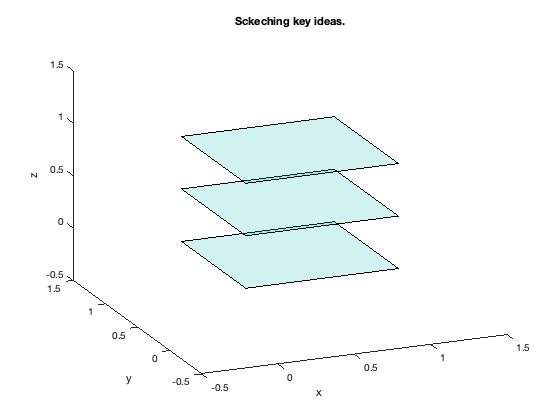

X = [0 1 1 0];
Y = [0 0 1 1];
Z_0 = [0 0 0 0];
X = [0 1 1 0];
Y = [0 0 1 1];
Z_05 = [0.5 0.5 0.5 0.5];
X = [0 1 1 0];
Y = [0 0 1 1];
Z_1 = [1 1 1 1];
C = [0.5];

figure
axis ([-0.5 1.5 -0.5 1.5 -0.5 1.5])
hold on
% labelling
zlabel('z');ylabel('y');xlabel('x');
% Create title
title('Sckeching key ideas.');
%% drawing the figure
fill3(X,Y,Z_0,C);
fill3(X,Y,Z_05,C);
fill3(X,Y,Z_1,C);
alpha 0.2
view([-22.85 25.81])

Skull perimeter. Circles means the border of skull in the Dicom image.

Ptos=circle([0.5 0.5],0.2,'n',64)

Ptos =     0.7000    0.6990    0.6962    0.6914    0.6848    0.6764    0.6663    0.6546    0.6414    0.6269    0.6111    0.5943    0.5765    0.5581    0.5390    0.5196    0.5000    0.4804    0.4610    0.4419    0.4235    0.4057    0.3889    0.3731    0.3586    0.3454    0.3337    0.3236    0.3152    0.3086    0.3038    0.3010    0.3000    0.3010    0.3038    0.3086    0.3152    0.3236    0.3337    0.3454    0.3586    0.3731    0.3889    0.4057    0.4235    0.4419    0.4610    0.4804    0.5000    0.5196
    0.5000    0.5196    0.5390    0.5581    0.5765    0.5943    0.6111    0.6269    0.6414    0.6546    0.6663    0.6764    0.6848    0.6914    0.6962    0.6990    0.7000    0.6990    0.6962    0.6914    0.6848    0.6764    0.6663    0.6546    0.6414    0.6269    0.6111    0.5943    0.5765    0.5581    0.5390    0.5196    0.5000    0.4804    0.4610    0.4419    0.4235    0.4057    0.3889    0.3731    0.3586    0.3454    0.3337    0.3236    0.3152    0.3086    0.3038    0.3010    0.3000  

plot3(Ptos(1,:), Ptos(2,:),ones(1,64),'-r','LineWidth',3)
Ptos_05=circle([0.5 0.5],0.3,'n',64)

Ptos_05 =     0.8000    0.7986    0.7942    0.7871    0.7772    0.7646    0.7494    0.7319    0.7121    0.6903    0.6667    0.6414    0.6148    0.5871    0.5585    0.5294    0.5000    0.4706    0.4415    0.4129    0.3852    0.3586    0.3333    0.3097    0.2879    0.2681    0.2506    0.2354    0.2228    0.2129    0.2058    0.2014    0.2000    0.2014    0.2058    0.2129    0.2228    0.2354    0.2506    0.2681    0.2879    0.3097    0.3333    0.3586    0.3852    0.4129    0.4415    0.4706    0.5000    0.5294
    0.5000    0.5294    0.5585    0.5871    0.6148    0.6414    0.6667    0.6903    0.7121    0.7319    0.7494    0.7646    0.7772    0.7871    0.7942    0.7986    0.8000    0.7986    0.7942    0.7871    0.7772    0.7646    0.7494    0.7319    0.7121    0.6903    0.6667    0.6414    0.6148    0.5871    0.5585    0.5294    0.5000    0.4706    0.4415    0.4129    0.3852    0.3586    0.3333    0.3097    0.2879    0.2681    0.2506    0.2354    0.2228    0.2129    0.2058    0.2014    0.200

plot3(Ptos_05(1,:), Ptos_05(2,:),0.5*ones(1,64),'-g','LineWidth',3)
Ptos_1=circle([0.5 0.5],0.5,'n',64)

Ptos_1 =     1.0000    0.9976    0.9904    0.9785    0.9619    0.9410    0.9157    0.8865    0.8536    0.8172    0.7778    0.7357    0.6913    0.6451    0.5975    0.5490    0.5000    0.4510    0.4025    0.3549    0.3087    0.2643    0.2222    0.1828    0.1464    0.1135    0.0843    0.0590    0.0381    0.0215    0.0096    0.0024         0    0.0024    0.0096    0.0215    0.0381    0.0590    0.0843    0.1135    0.1464    0.1828    0.2222    0.2643    0.3087    0.3549    0.4025    0.4510    0.5000    0.5490
    0.5000    0.5490    0.5975    0.6451    0.6913    0.7357    0.7778    0.8172    0.8536    0.8865    0.9157    0.9410    0.9619    0.9785    0.9904    0.9976    1.0000    0.9976    0.9904    0.9785    0.9619    0.9410    0.9157    0.8865    0.8536    0.8172    0.7778    0.7357    0.6913    0.6451    0.5975    0.5490    0.5000    0.4510    0.4025    0.3549    0.3087    0.2643    0.2222    0.1828    0.1464    0.1135    0.0843    0.0590    0.0381    0.0215    0.0096    0.0024         0

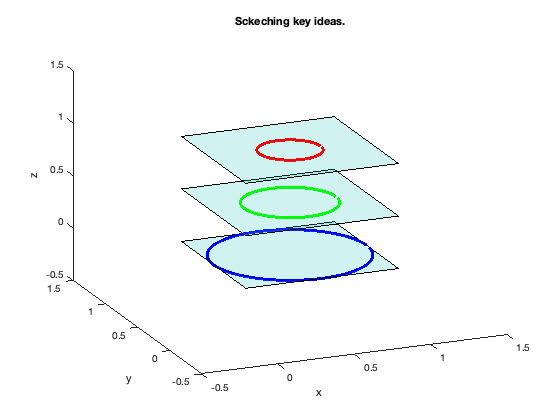

plot3(Ptos_1(1,:), Ptos_1(2,:),zeros(1,64),'-b','LineWidth',3)

## Three fiducial for registering

F_S=[0.5 0.5-0.2 1;...% x,y and  z of the first fiducial
    0.5-(0.3/sqrt(2)) 0.5-(0.3/sqrt(2)) 0.5;...x,y and  z of the second fiducial
    0.5+(0.5/sqrt(2)) 0.5-(0.5/sqrt(2)) 0]'

F_S =     0.5000    0.2879    0.8536
    0.3000    0.2879    0.1464
    1.0000    0.5000         0


## Ploting the fiducial

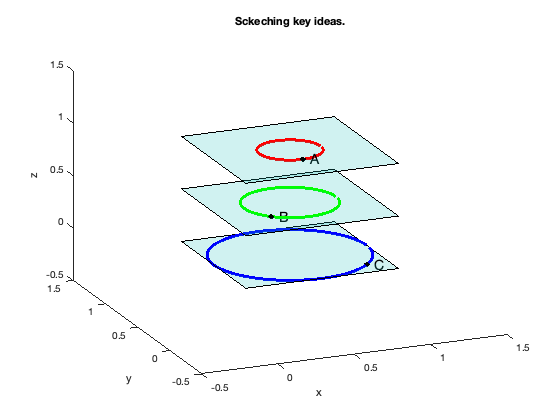

[x,y,z] = sphere;
surf(0.015*x+F_S(1,1),0.015*y+F_S(2,1),0.015*z+F_S(3,1))  
surf(0.015*x+F_S(1,2),0.015*y+F_S(2,2),0.015*z+F_S(3,2))  
surf(0.015*x+F_S(1,3),0.015*y+F_S(2,3),0.015*z+F_S(3,3))
text(F_S(1,1)+0.05,F_S(2,1),F_S(3,1) ,{'A'},'FontSize',14)
text(F_S(1,2)+0.05,F_S(2,2),F_S(3,2) ,{'B'},'FontSize',14)
text(F_S(1,3)+0.05,F_S(2,3),F_S(3,3) ,{'C'},'FontSize',14)

## Drawing the triangle A-B-C

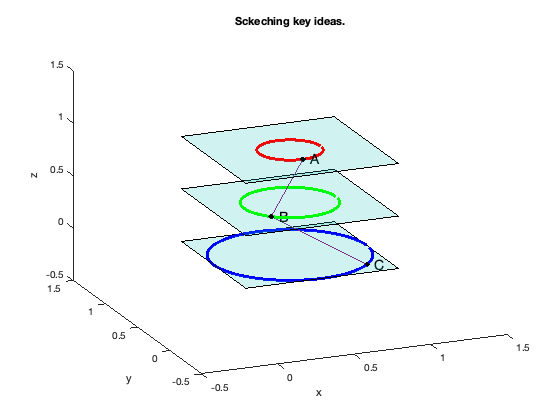

plot3(F_S(1,:),F_S(2,:),F_S(3,:)) 

## References Frames

Plotting the Reference Frame of the Skull-{S}

trplot(eye(4), 'frame','S','length',0.4,'text_opts', {'FontSize', 14},'arrow','color', 'b','thick',1,...
           'axis', [-0.5 1.5 -0.5 1.5 -0.5 1.5])

For debuging, imagine Wordl {W} is unkown

WRF=eul2tr(0.1,0.2,0.3)

WRF =     0.9021   -0.3836    0.1977         0
    0.3875    0.9216    0.0198         0
   -0.1898    0.0587    0.9801         0
         0         0         0    1.0000


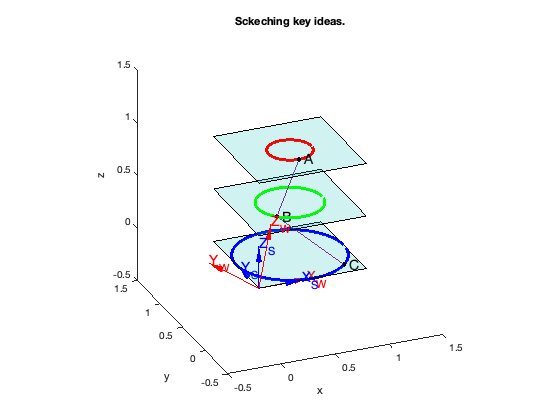

trplot(WRF, 'frame','W','length',0.6,'text_opts', {'FontSize', 14},'arrow','color', 'r','thick',1,...
           'axis', [-0.5 1.5 -0.5 1.5 -0.5 1.5])       

## Measuring fiducial with Puma

We apply an operator to the Fiducials in {S}

FK_W=t2r(WRF)*F_S% Fiducial in WRF. We will use the puma to touch them

FK_W =     0.5337    0.2481    0.7138
    0.4901    0.3868    0.4657
    0.9028    0.4523   -0.1534


## To correctly register the fiducial see the example Skull_pose_stimation.mlx

*Copyright 2015 The MathWorks, Inc.*